# ULISE Filter for Fault Detection 

This example demonstrates the ULISE algorithm [1] on a discrete-time, linear time-invariant system subject to unknown inputs (faults) [2]. The objective is to simultaneously estimate the optimal state $\hat{x}_{k|k} \in \mathbb{R}^5$ and unknown input, also referred to as disturbances,  $\hat{d}_{k-1}  \in \mathbb{R}^3$ for a plant subject to white Gaussian process noise $w_k \in \mathbb{R}^5$, white Gaussian measurement noise $v_k \in \mathbb{R}^3$, and a zero control input $u_k = 0 \in \mathbb{R}^1$, as shown in the following diagram.

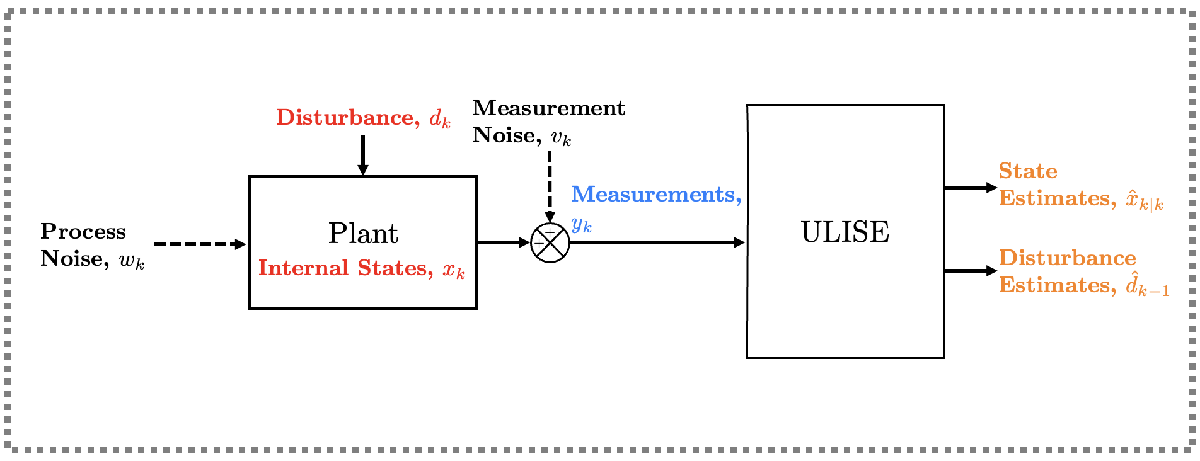

Figure 1: Block diagram of a plant and the ULISE filter with no control iinput.

Let the example plant have the following state-space matrices.

A = [0.5    2   0   0   0;
     0      0.2 1   0   1; 
     0      0   0.3 0   1; 
     0      0   0   0.7 1;
     0      0   0   0   0.1]; 

B = zeros(size(A,1),1);

C = blkdiag(1,1,1,1,1);

D = zeros(size(C,1),1);

G = [1  0   -0.3;
     1   0   0;
     0   0   0;
     0   0   0;
     0   0   0];

H = [0  0   1;
     0  0   0; 
     0  1   0; 
     0  0   0; 
     0  0   0]; 

We specify the measurement and process noise covariances matrices as follows. These would typically be based off empirical data from your system.

R = 1e-2* [1    0   0   0.5 0;
           0    1   0   0   0.3; 
           0    0   1   0   0; 
           0.5  0   0   1   0; 
           0    0.3 0   0   1];

Q = 1e-4* [1    0   0   0   0; 
           0    1   0.5 0   0; 
           0    0.5 1   0   0; 
           0    0   0   1   0; 
           0    0   0   0   1]; 

We also define the number of time steps$(K = 1000)$, the initial state estimate $\hat{x}_0$, the true initial state $x_0$ and the initial state error covariance matrix $P_{x_0}$. In this example, $$$\hat{x}_0 = x_0$$
$.

K = 1000;

x0 = zeros(size(A,1),1);        % Initial true state 
xhat0 = zeros(size(A,1),1);     % Initial state estimate 
P_x0 = eye(size(A,1))*1e6;      % Initial state error covariance 


Next, we define the known input $u$ and the true disturbance trajectory $d$ as column vectors for all $K$time steps. 

u = zeros(1,K);

d = zeros(size(G,2),K); 
d(1,500:700) = 1*ones(size(d(1,500:700)));

for j = 100:800
    d(2,j) = 1/700*(j-100);
end
d(3,[500:549 600:649 700:749]) = 3*ones(size(d(3,[500:549 600:649 700:749])));
d(3,[550:599 650:699 750:799]) = -3*ones(size(d(3,[550:599 650:699 750:799])));


The process and measurement noise covariance matrices $Q$ and $R$ are used to generate the process noise $w$ and measurement noise $v$. 

SigmaQ = chol(Q);
w = (randn(K,size(A,1))*SigmaQ)';

SigmaR = chol(R);
v = (randn(K,size(C,1))*SigmaR)';

We model the system dynamics in state space to generate noisy measurement and state time series, $y$ and $x$ respectively, over all time steps.

% Preallocate x and y 
x = zeros(size(A,1),K);     
y = zeros(size(C,1),K);

x(:,1)=x0;

% Generate x and y
for i=1:K
    y(:,i)=C*x(:,i)+D*u(i)+H*d(:,i)+v(:,i);
    if i<K
        x(:,i+1)=A*x(:,i)+B*u(i)+G*d(:,i)+w(:,i);
    end
end

Using ULISE, we can estimate the state and disturbance vectors, their corresponding error covariance matrices, and the cross-covariance matrix $P^{xd}$.

[xhat_UL,Px_UL,dhat_UL,Pd_UL,Pxd_UL] = ULISE(A,B,C,D,G,H,Q,R,K,u,y,xhat0,P_x0);

t_zeros =     0.3000
    0.8000


Next, we display the diagonal elements of the state and unknown input covariance matrices at the final timestep, $k = K$, which correspond to the variances of each state and unknown input. 

% Diagonal elements of state covariance matrix P
display([Px_UL(1,1,end),Px_UL(2,2,end),Px_UL(3,3,end),Px_UL(4,4,end),Px_UL(5,5,end)])

    0.1843    0.0091    0.0002    0.0004    0.0001




% Diagonal elements of the covariance matrix for d
display([Pd_UL(1,1,end-1),Pd_UL(2,2,end-1),Pd_UL(3,3,end-1)])

    0.0099    0.0102    0.1923



Below provides example code to generate visualizations of your system and filter dynamics. Figure 1 plots ULISE state and disturbance estimates against true values over time, and Figure 2 plots the traces of their error covariance matrices over time.

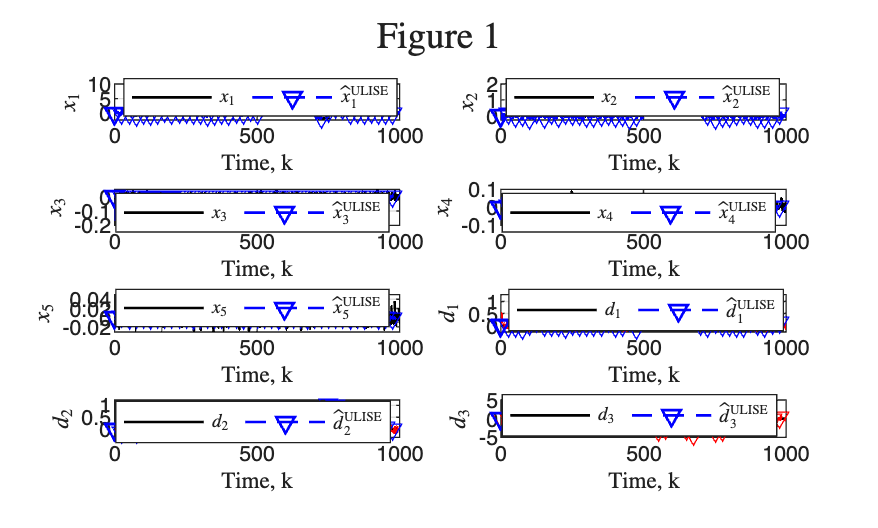

set(0,'defaulttextinterpreter','latex')
num=25; k=1:K;

% Figure 1
fig1 = figure;
sgtitle('Figure 1')

subplot(4,2,1)
plot(k,x(1,:),'k-',k,xhat_UL(1,:),'b--','LineWidth',1);
hold on
plot(k(1:num:end),xhat_UL(1,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$x_1$')
h=legend(h1,'$x_1$','$\hat{x}^{\rm ULISE}_1$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')


subplot(4,2,2)
plot(k,x(2,:),'k-',k,xhat_UL(2,:),'b--','LineWidth',1);
hold on
plot(k(1:num:end),xhat_UL(2,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$x_2$')
h=legend(h1,'$x_2$','$\hat{x}^{\rm ULISE}_2$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

subplot(4,2,3)
plot(k,x(3,:),'k-',k,xhat_UL(3,:),'b--','LineWidth',1);
hold on
plot(k(1:num:end),xhat_UL(3,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$x_3$')
h=legend(h1,'$x_3$','$\hat{x}^{\rm ULISE}_3$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

subplot(4,2,4)
plot(k,x(4,:),'k-',k,xhat_UL(4,:),'b--','LineWidth',1);
hold on
plot(k(1:num:end),xhat_UL(4,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$x_4$')
h=legend(h1,'$x_4$','$\hat{x}^{\rm ULISE}_4$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

subplot(4,2,5)
plot(k,x(5,:),'k-',k,xhat_UL(5,:),'b--','LineWidth',1);
hold on
plot(k(1:num:end),xhat_UL(5,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$x_5$')
h=legend(h1,'$x_5$','$\hat{x}^{\rm ULISE}_5$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

subplot(4,2,6)
plot(k,d(1,:),'k-',k,dhat_UL(1,:),'r--','LineWidth',1);
hold on
plot(k(1:num:end),dhat_UL(1,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$d_1$')
h=legend(h1,'$d_1$','$\hat{d}^{\rm ULISE}_1$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

subplot(4,2,7)
plot(k,d(2,:),'k-',k,dhat_UL(2,:),'r--','LineWidth',1);
hold on
plot(k(1:num:end),dhat_UL(2,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$d_2$')
h=legend(h1,'$d_2$','$\hat{d}^{\rm ULISE}_2$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

subplot(4,2,8)
plot(k,d(3,:),'k-',k,dhat_UL(3,:),'r--','LineWidth',1);
hold on
plot(k(1:num:end),dhat_UL(3,1:num:end),'rv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$d_3$')
h=legend(h1,'$d_3$','$\hat{d}^{\rm ULISE}_3$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

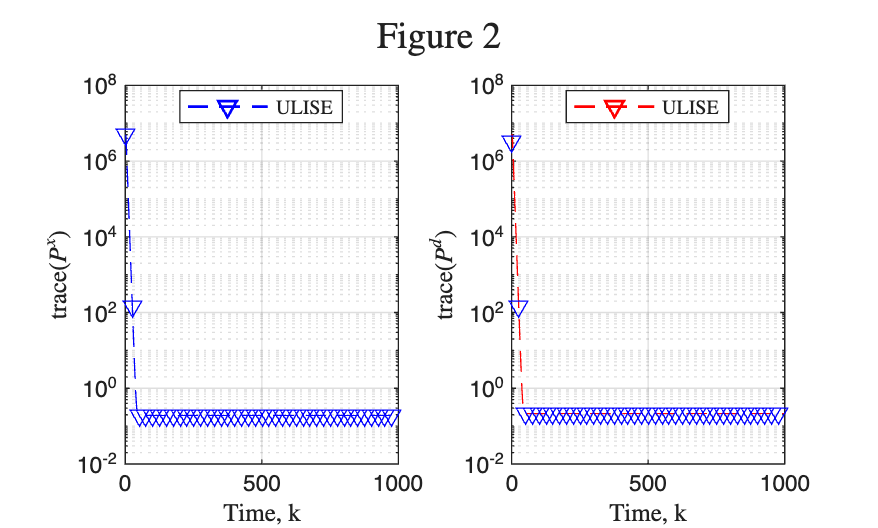

% Figure 2
trX_UL=zeros(k(end),1);
trD_UL=zeros(k(end),1);


for i=k
   trX_UL(i)=trace(Px_UL(:,:,i));
   trD_UL(i)=trace(Pd_UL(:,:,i)); 
end


fig2 = figure;
sgtitle('Figure 2')

subplot(1,2,1)
semilogy(k,trX_UL,'b--');
hold on
semilogy(k(1:num:end),trX_UL(1:num:end),'bv');
grid on
h1=plot(0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('trace($P^x$)')
h=legend(h1,'ULISE');
set(h,'Interpreter','latex','Location','Best')

subplot(1,2,2)
semilogy(k,trD_UL,'r--');
hold on
semilogy(k(1:num:end),trD_UL(1:num:end),'bv');
grid on
h1=plot(0,0,'rv--','LineWidth',1);
xlabel('Time, k')
ylabel('trace($P^d$)')
h=legend(h1,'ULISE');
set(h,'Interpreter','latex','Location','Best')

### References:

[1] Yong, S. Z., Zhu, M., & Frazzoli, E. (2013). A unified filter for simultaneous input and state estimation of linear discrete-time stochastic systems. arXiv preprint arXiv:1309.6627. Available at: [https://arxiv.org/abs/1309.6627](https://arxiv.org/abs/1309.6627)

[2] Keller, J. Y., Summerer, L., Boutayeb, M., & Darouach, M. (1996). Generalized likelihood ratio approach for fault detection in linear dynamic stochastic systems with unknown inputs. International journal of systems science, 27(12), 1231-1241.

% AUTHOR       : Daniel Lawson, adapted from Sze Zheng Yong
% DATE CREATED : October 9, 2025
% REPOSITORY   : https://github.com/dalawson0/SISE.git